# Modeling Projectile Motion

This objective of this project is to model the motion of a ball that is thrown in some direction as a projectile. The first step will be to model the projectile using the basic kinematic equations, which ignore air resistance. Once this model has been created, another model that accounts for air resistance can be created. The differnece in the ball's motion between the two methods can then be compared. 

## Projectile Motion Without Drag

### Equations of Motion

The basic kinematic equations can be used to model projectile motion without air resistance. You are most likely familaiar with they equations as they are covered in your physics classes. The equation that we can use to model the veritcal height of the projectile is


$$y = y_0+v_{0_y}t+\frac{1}{2}a_yt^2$$


where

    $y$ -- is the current vertical position of the ball

    $y_0$ -- is the initial position of the ball

    $v_{y_{0\;} }$ -- is the initial vertical velcoity of the ball

    $a\;$-- is the vetical acceleration (In this case it will be the acceleration due to gravity)

    $t$-- is the time elapsed from start

The horizontal motion of the ball is much simpiler and can be modeled by 


$$x=x_0 +v_{0_x } t$$


where 

    $x$ -- is the current horizontal position of the ball

    $x_0$-- is the initial horizontal position of the ball

    $v_{0_x }$-- is the initial horizontal velocity of the ball

To make our example simpilar, we will set the starting position of the ball to be at an intial positon of $x_0 ,y_0 =0\ldotp$ The initial velocity of the ball is provided in terms of a initial velocity, $v_0 ,$ and an angle, $\theta ,$ from the horizontal axis (ground in our case). To extract the vertical and horizontal initial velcoties from these values, the following equations can be used.

    
$$\begin{array}{l}
v_{0_x } =v_{0\;} \;\mathrm{cos}\left(\theta \right)\\
v_{0_y } =v_{0\;} \;\mathrm{sin}\left(\theta \right)
\end{array}$$


We are now ready to create our model.

### Modeling in MATLAB

MATLAB is a numerical computing program that is a very effective tool to use when doing mathematics.  MATLAB is similar to many other computing program languages, but is tailored to computing mathematics. Modelling our ball system will be used to introduce you to the programming basics of MATLAB. The first step is declare the variables we will need in our program.

To declare a variable, first create a variable name. You then define a value that will stored in that variable. The value stored by a variable can be modified during you program if you desire such. Be sure to add a semicolon (;) at the end of each line of code. This prevents it from being displayed in the output window. 

% VARIABLE DECLERATION
% In this section, you will declare all the variables you will need 
% for the simulation. An example variable declaration is provided below 
% for the acceleration due to gravity. You will need to declare
% the remaining variables defiend below:
%   angle of launch (theta)
%   initial velocity (v_0)
%   component of initial velocity in x direction (v_0_x)
%   component of initial velocity in y direction (v_0_y)
%       HINT: To get cosine and sine use cosd(_your variable_) and 
%             sind(your_variable), respectively.
%   initial x position (x_0)
%   initial y position (y_0)
%   amount of time that occurs between position calcualtions (timeStep)

a = -9.81;      % acceleration due to gravity (m/s)
v_0 = 25;      % initial velocity (m/s)
theta = 45;     % launch angle in degrees

v_0_x = v_0*cosd(theta);    % initial velocity in x direction
v_0_y = v_0*sind(theta);    % initial velocity in y direction

x_0 = 0;    % initial x position (m)
y_0 = 0;    % initial y positon (m)

time_step = 0.05;   % time increment between position calculations

With our variables declared, we can now translate the equations governing our system into code. The first section is code used to store the results from the simulation; you do not need to worry about them. 

%%%%% DO NOT WORRY ABOUT THIS SECTION OF CODE %%%%%
time_to_ground = (-v_0_y - sqrt(v_0_y^2 - 4*0.5*a*x_0))/a;
num_iterations = round(time_to_ground/time_step,0)+1;

time = 0:time_step:time_step*(num_iterations-1);
x = zeros(1,num_iterations);
y = zeros(1,num_iterations);
x(num_iterations) = v_0_x*time_to_ground;
y(num_iterations) = 0;
%%%%% END SECTION OF CODE %%%%%

% CREATING MODEL
% To generate the model, a for loop (loop that runs a specified number of
% times) is created. Translate the position update equations provided 
% above into code to calcualte the x,y position of the ball at each time 
% step. Use the time(iteration) to access the amount of time elapsed from the
% ball's launch. An exponent can be insterted using ^.

for iteration = 1:num_iterations-1
    x(iteration) = x_0 + v_0_x*time(iteration);
    y(iteration) = y_0 + v_0_y*time(iteration) + 0.5*a*time(iteration)^2;
end

Using the model created we can now create plots to display our model's results. An example is provided below that plots the x and y position of the ball from launch to landing on the ground. Create two more plots, one that plots the horizontal distance travelled vs time and another that tracks the height of the ball over time. 

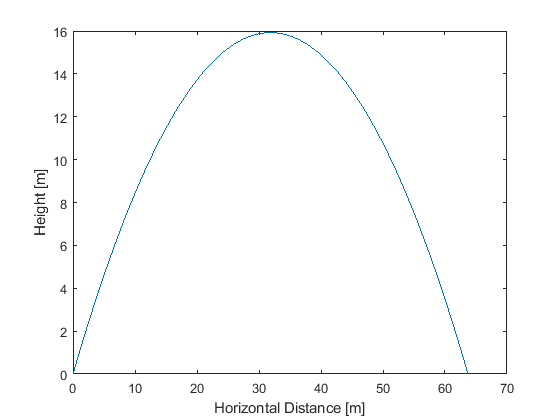

% Height vs. Horizontal Distance
figure(1)
plot(x,y)
xlabel('Horizontal Distance [m]')
ylabel('Height [m]')

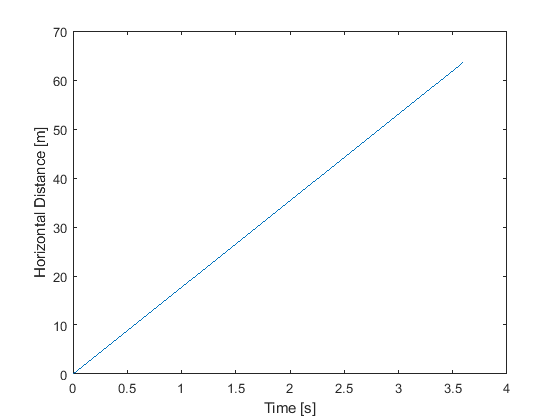


% Horizontal Distance vs Time
figure(2)
plot(time,x)
xlabel('Time [s]')
ylabel('Horizontal Distance [m]')

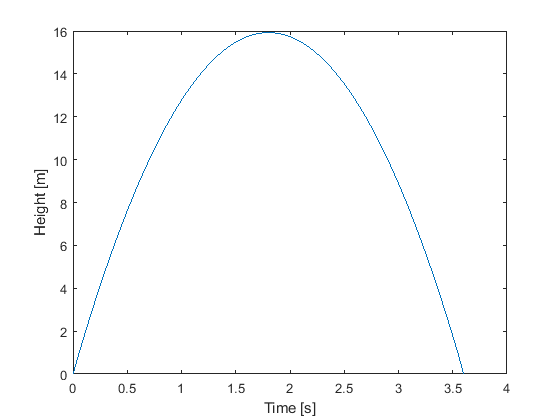


% Height vs. Distance
figure(3)
plot(time,y)
xlabel('Time [s]')
ylabel('Height [m]')

## Projectile Motion With Drag

### Momentum Update Method & Forces

To incorporate drag into projectile motion we need to determine how drag influences the ball's motion. Drag will reduce both the horizontal and vertical travel of the ball. Intuitively if something is introduced to counter the motion of the ball, it is expected that the horizontal and vertical distances travelled by the ball will be reduced.

The force due to drag acting on a body, $F_d$, can be determiend using the follwoing equation.


$$F_d =C_d \frac{1}{2}\rho \;v^2 A$$


where 

    $C_d$ -- is the drag coefficent of the body

    $\rho \;$ -- density of air

    $v$ -- speed of the body

    $A\;$-- cross-sectional area of tthe body

Since this force is dependent on velocity, it will vary at every instance of the ball's travel. To model this we will use the momentum update method. This method accounts for the small changes in the forces acting on the body over time. The momentum update method is derived from Newton's Second Law and uses


$$\mathrm{Force}*\mathrm{dt}=\mathrm{mass}*\Delta v$$


This equation is rearranged to solve for the change in velcoity, $\Delta v$. A small change in time is denoted by $\mathrm{dt}$. Once the change in velcoity is known, the x and y velcoity and position can be updated.

### Modeling in MATLAB

% VARIABLE DECLERATIONS
% Similar to first variable declaration section, you will declare the
% variables that you are to use in calcualting the positon of the ball when
% accounting for drag experienced by the ball. The variables that will need
% to be declared are:
%   mass of the ball (mass)
%   cross-sectional area of ball (cross_section_area)
%   coefficient of drag, 0.5 [for a ball] (c_d)
%   density of air, 1.2 (rho)
%   gravity constant, 9.81
%   initial velocity of the ball (v_0)
%   angle of launch (theta)
%   velocity of ball in x-direction, define it to be x-component of initial
%       velocity (v_x)
%   velocity of ball in y-direction, define it to be x-component of initial
%       velocity (v_y)
%   x position of the ball, define it to be the intial positon of the ball that
%       you defined above (x_drag)
%   y position of the ball, define it to be the intial positon of the ball that
%       you defined above (y_drag)
%   time step between momentum updates, you want this value to be small
%       ~0.01 seconds (time_step)
%   total flight time of the ball (flight_time)

mass = 0.3;   % Mass of the ball in kg
cross_section_area = pi*(0.5/2)^2; % cross-sectional area of the ball (m^2)
c_d = 0.5;  % coeffcient of drag 
rho = 1.2;  % density of air (kg/m^3)
g = 9.81;   % acceleration due to gravity (m/s)

v_x = v_0*cosd(theta);    % initial velocity in x direction
v_y = v_0*sind(theta);    % initial velocity in y direction

x_drag = x_0;    % the current postion of the ball (m)
y_drag = y_0;    % the current position of the ball (m)

time_step = 0.005;   % time step between momentum updates (s)
flight_time = 0;    % keeps track of ball's flight time (s)

%%% DO NOT EDIT THIS SECTION OF CODE %%%
% This section of code creates variables that will track the results from the drag model so they
% can be plotted

x_drag_track = [x_drag]; % keeps track of the x position of the ball for each iteration of the drag simulation
y_drag_track = [y_drag]; % keeps track of the y position of the ball for each iteration of the drag simulation
time_drag = [0]; % keeps track of the time from launch that each position update occured at
%%% END OF DO NOT EDIT SECTION %%%

With all the variables declared, the model of the ball's travel can be created. This model is generated within a while loop which runs on the condtiont that the ball has not hit the ground yet. The steps for the momentum update method are provided below.

- Calculatel, the new *x *and *y *position of the ball over the time step set using the current velocity of the ball. 

- Calcualte the angle relative to the x-axis that the ball is traveliing at. Hint use the *x* and *y* velcoity of the ball and the *atand()  *function. Also calcualte the magnitude of the velocity using the *x *and *yI*velcoity components in  Pythagorems Theorem. HINT: Draw a picture to help visualize what is happeneing here.

- Translate the drag equation into code.

- Write the force balances for the x and y direction. Use cosine and sine to determine the x and y drag forcee components. HINT: Draw a FBD to help visualize what forces act on the ball. Don't forget about gravity. 

- Rearrange and translate the momentum update equation to determine the change in the *x *and *y *velcoities of the ball. 

- Update the *x *and *y* velocity of the ball by adding the change in velcoity to the current *x *and *y *velocity of the ball. These velocities will be used to calculate the position of the ball in the next iteration of the loop.

- Add a time increment to keep track of the flight time of the ball.

% MOMENTUM UPDATE MODEL
% Insert you model code inside the for loop to calcualte the positon of the
% ball.
figure(4)
while(y_drag >= 0)
    x_drag = x_drag + v_x * time_step;
    y_drag = y_drag + v_y * time_step;
    
    alpha = atand(v_y/v_x);
    v = sqrt(v_y^2+v_x^2);
    
    F_d = c_d*0.5*rho*v^2*cross_section_area;
        
    F_x = -F_d*cosd(alpha);
    F_y = -F_d*sind(alpha) - mass*g;
    
    delta_V_x = F_x*time_step/mass;
    delta_V_y = F_y*time_step/mass;
    
    v_x = v_x + delta_V_x;
    v_y = v_y + delta_V_y;
                  
    flight_time = flight_time + time_step;
    
    %%% DO NOT EDIT THIS SECTION OF CODE %%%
    if y_drag >= 0
        x_drag_track = [x_drag_track, x_drag];
        y_drag_track = [y_drag_track, y_drag];
        time_drag = [time_drag, flight_time];
    end 
    %%% END OF DO NOT EDIT SECTION %%%
end

With the drag simulation now completed, we can porceed with plotting the simulation results. If you want to compare the two simulations results on the same plot you will need to use the *hold on* command, which holds thefigure so that multiple lines can be plotted. Once all the desired items are plotted, you can turn off this command with *hold off.*

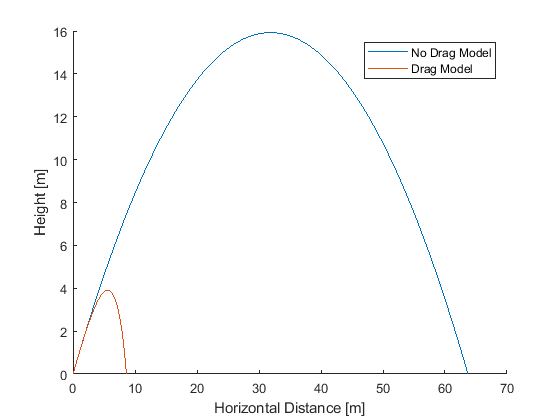

% PLOTTING
% Plot the results agaisnt the results from the ideal model
% To access the drag simulation results use the x_drag_track, y_drag_track
% and time_drag variables for the x position, y position and time values
% respectively.

figure(4)
hold on;
plot(x,y);
plot(x_drag_track,y_drag_track)
hold off;
xlabel('Horizontal Distance [m]')
ylabel('Height [m]')
legend('No Drag Model','Drag Model')

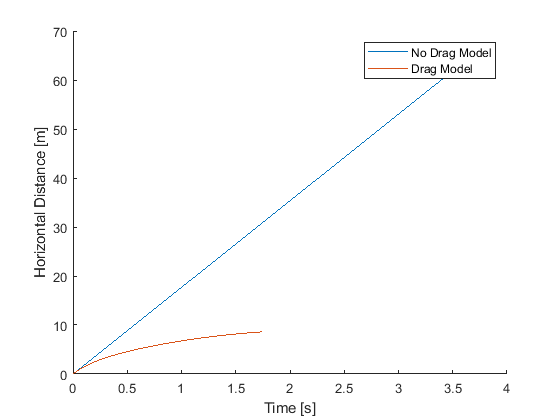


figure(5)
hold on;
plot(time,x)
plot(time_drag,x_drag_track)
hold off;
xlabel('Time [s]')
ylabel('Horizontal Distance [m]')
legend('No Drag Model','Drag Model')

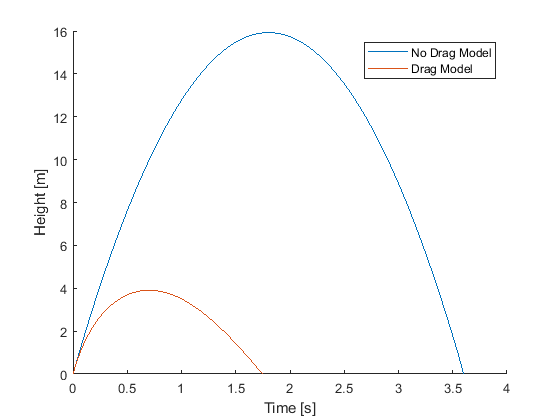


figure(6)
hold on;
plot(time,y)
plot(time_drag,y_drag_track)
hold off;
xlabel('Time [s]')
ylabel('Height [m]')
legend('No Drag Model','Drag Model')